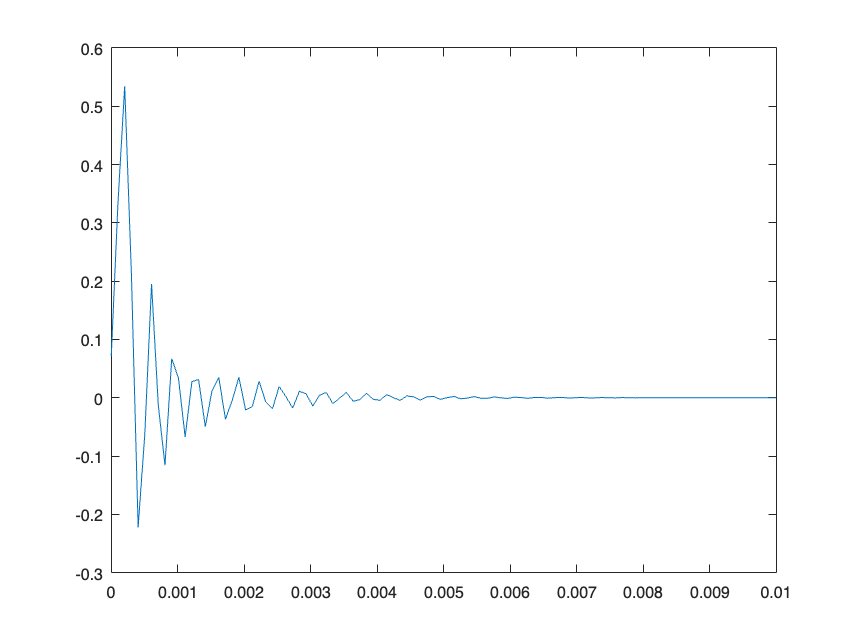

fc = 100e3;
fs = 1e6;
rp = 1;
% x: input signal
% y: filtered output signal

% Calculate analog cutoff frequency and convert to digital
wc = 2*pi*fc; % analog cutoff frequency
wd = 2*pi*fc/fs; % digital cutoff frequency

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(wd, 0.5*wd, rp, 60);
[b, a] = cheby1(n, rp, Wn);


L = 1e-2;
N_L = 100;
t = linspace(0, L, N_L); % delta function
x = [1, zeros(1, N_L-1)];

% Filter input signal using the filter coefficients
y = filter(b, a, x);
% Calculate frequency response
[H, w] = freqz(b, a, N_L);

figure
plot(t, y)

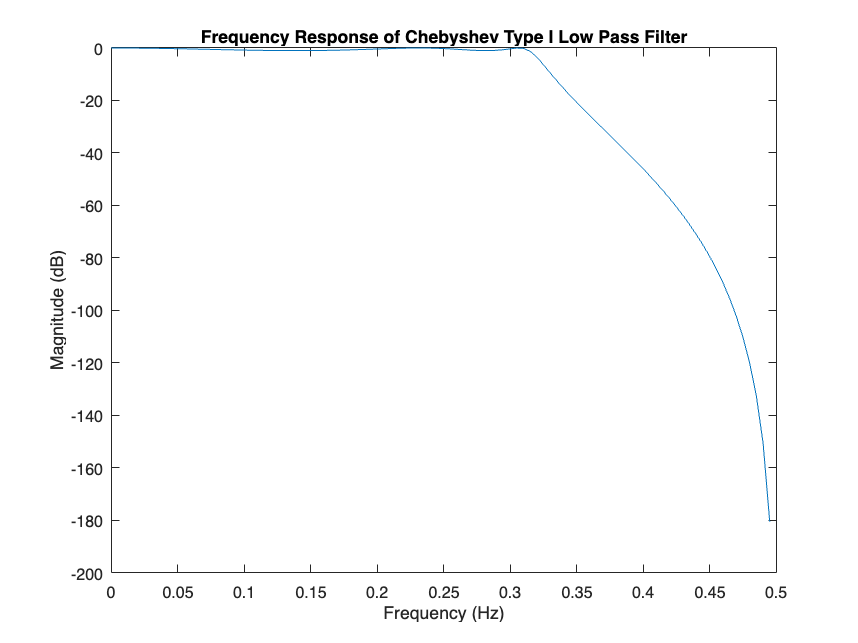


% Plot frequency response
figure;
plot(w/(2*pi), 20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Chebyshev Type I Low Pass Filter');

New

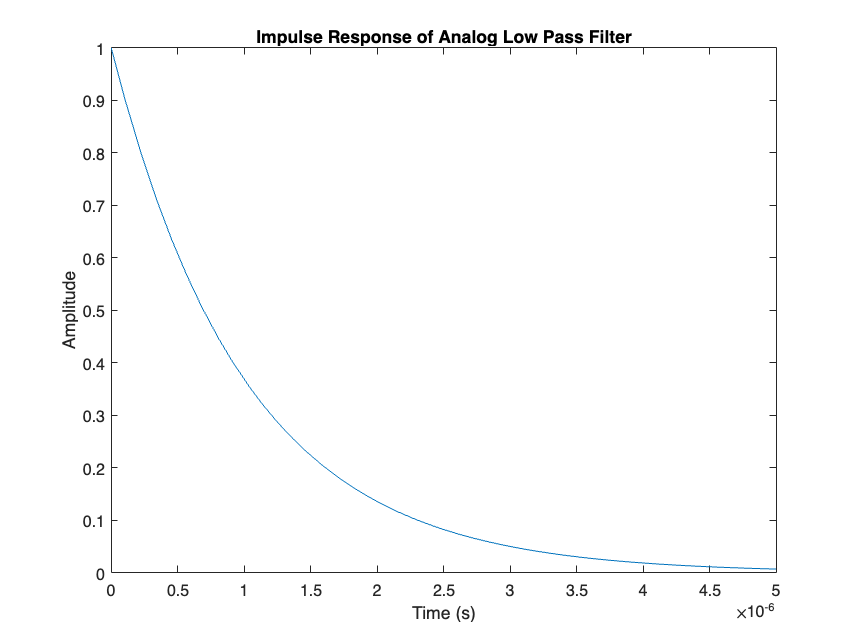

% Define the filter parameters
R = 1;      % Resistance in ohms
C = 1e-6;   % Capacitance in farads
fc = 1/(2*pi*R*C);  % Cutoff frequency in Hz

% Create the transfer function H(s)
syms s
H = (1/(2*pi*fc))/(1 + s/(2*pi*fc));

% Find the impulse response Gamma(t)
syms t
Gamma_t = ilaplace(H);

% Plot the impulse response
figure
fplot(Gamma_t, [0, 5*R*C]);
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response of Analog Low Pass Filter');

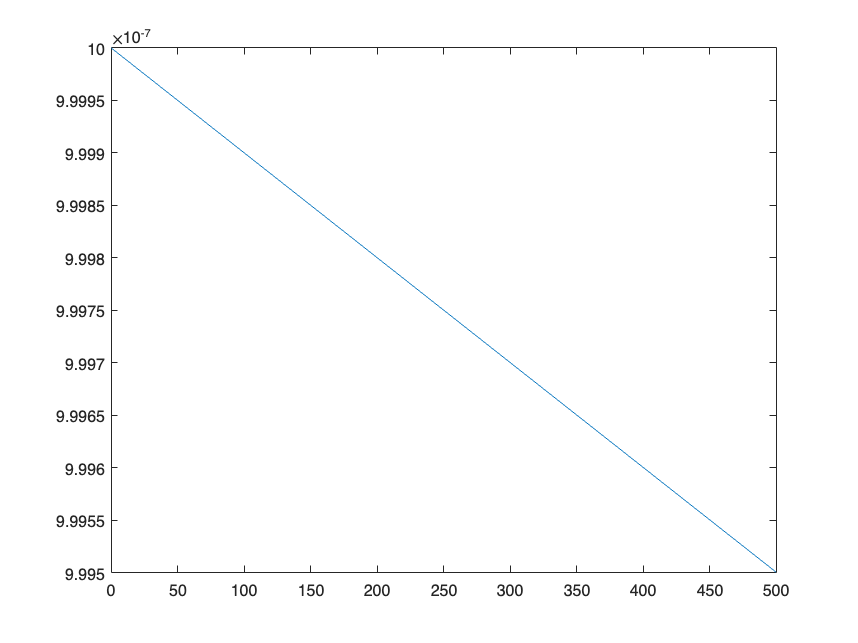

figure
fplot(H, [0, 500])

ODE

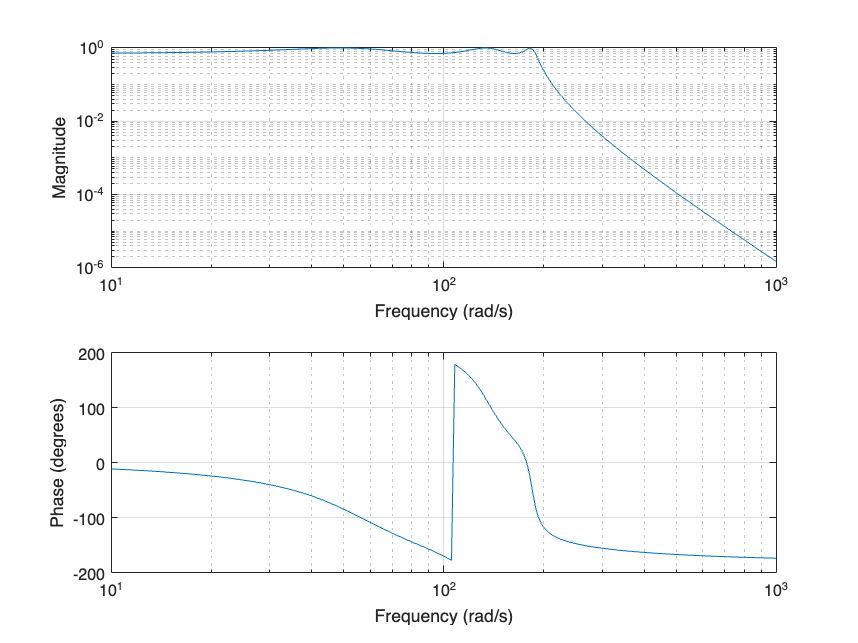

clear all
[z,p,k] = cheb1ap(6,3);       % Lowpass filter prototype
[num,den] = zp2tf(z,p,k);     % Convert to transfer function form
Wo = 2*pi*30;
[bt,at] = lp2lp(num,den,Wo);
figure
freqs(bt,at)

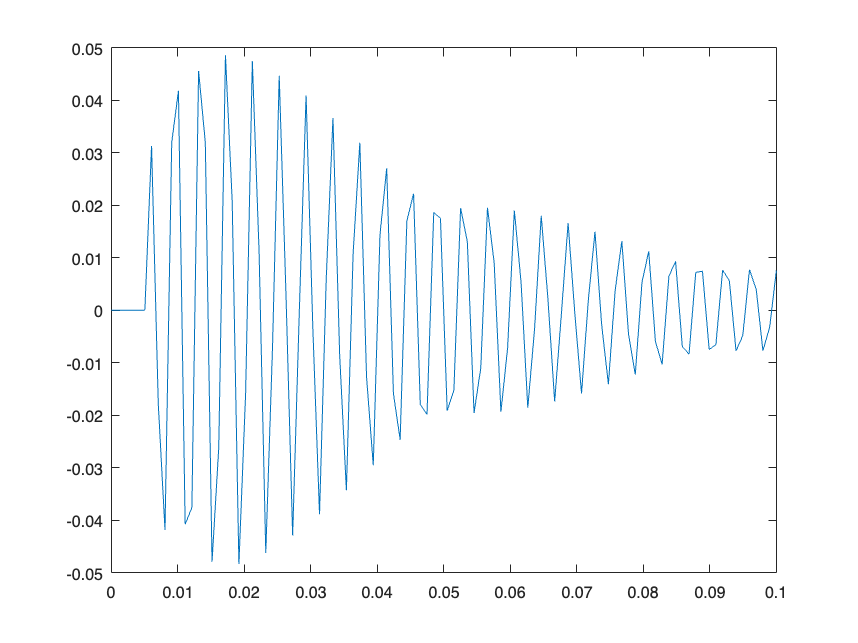

x = [1, zeros(1, 100-1)];
Gamma = filter(num, den, x); % Gamma(z)
figure
plot(linspace(0, 0.1, 100), Gamma)

l

% Filter specifications
Wp = 0.2;   % Passband edge frequency (in radians)
Ws = 0.3;   % Stopband edge frequency (in radians)
Rp = 1;     % Passband ripple (in dB)
Rs = 50;    % Stopband attenuation (in dB)

% Chebyshev Type I filter design
[N, Wn] = cheb1ord(Wp, Ws, Rp, Rs, 's');
[b, a] = cheb1ap(N, Rp);
[num, den] = bilinear(b, a, 1); % Bilinear transformation to convert to digital filter

Not enough input arguments.

Error in bilinear (line 82)
    validateattributes(fs,{'numeric'},{'scalar','real','finite','positive'},'bilinear','Fs',4);


% Impulse response of the filter
x = [1, zeros(1, 99)]; % Delta function input
y = filter(num, den, x); % Filter output

% Plot the impulse response
stem(y);
title('Impulse Response of Chebyshev Type I Low-Pass Filter');
xlabel('Sample Number');
ylabel('Filter Output');
